# Phase Portrait for Duffing's Equation

close all; clc

% creates two matrices:
% one for all the x-values on the grid (constant columns)
% one for all the y-values on the grid (constant rows)
y1 = linspace(-1.5,1.5,10);
y2 = linspace(-1,1,10);
[X,Y] = meshgrid(y1,y2);

Computing the Vector Field

% Generate two matrices, u and v. 
% U contains the value of y1'(0) at each x and y position
% V contains the value of y2'(0) at each x and y position
U = zeros(size(X));
V = zeros(size(X));
t = 0;

% numel iterates over the 1st column, then 2nd, ...
for i = 1:numel(X)
    y_dot = f(t, [X(i); Y(i)]); % pendulum equation
    U(i) = y_dot(1);
    V(i) = y_dot(2);
end

Plot the Vector Field

quiver(X,Y,U,V,'k');
xlabel('x')
ylabel('y')
axis tight equal;
title("Vector Field for Duffing's Equation")

Plotting solutions on the vector field for different initial conditions:

 
$$y_1(0)=y_{10}, \\
y_2(0)=y_{20}$$


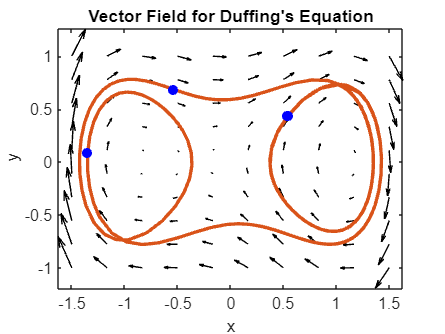

hold on
y10 = 0;
y20 = 0;
[ts,ys] = ode45(@f,[0 500],[y10; y20]);

% place circle at beginning of each period
% in the fundamental frequency
N = 180;
ts_end = ts(end-N:end);
ys1 = ys(end-N:end,1);
ys2 = ys(end-N:end,2);

% every fundamental period
TF = islocalmin(mod(ts_end,2*pi));

plot(ys1,ys2,'LineWidth',2)
scatter(ys1(TF),ys2(TF),'blue','filled') % fundamental period
hold off

Now plot the time series:

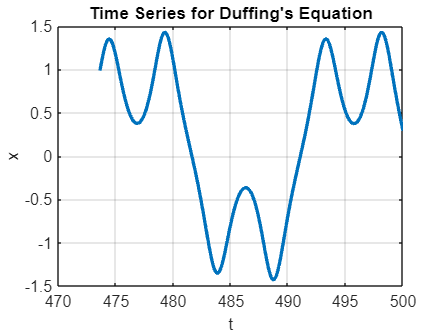

plot(ts_end, ys1,'LineWidth',2);
title("Time Series for Duffing's Equation")
grid on
xlabel('t')
ylabel('x')

Let $$y_1=x$ and $y_2=y$$.

function [y_dot] = f(t,y)
gamma=0.25;
omega=1;
delta=0.15;
y_dot(1,:) = y(2);
y_dot(2,:) = y(1)-y(1)^3-delta*y(2)+gamma*cos(omega*t);
end